# Transfer Learning Without DND

This script contains code to train the transfer learning model without deep network designer. You must run the solution script after line 19 to run this.

net = googlenet; 
layers = net.Layers;

## Resize Images to Alexnet Input Requirement

There are many ways to perform this process. The fastest is to use an augmentedImageDatastore, which will resize our imagedatastore in mini-batches as we pass images through the network for training.  

inputSize = net.Layers(1).InputSize(1:2);

DS = struct;

DS.auTrainDS = augmentedImageDatastore(inputSize,trainDS);
DS.auValDS = augmentedImageDatastore(inputSize,valDS);
DS.auTestDS = augmentedImageDatastore(inputSize,testDS);

## Modify the Network

In transfer learning the majority of the layers stay the same. We need to modify the last few layers to fit our specific dataset. 

Remember the 3 layers at the end of each network(the ones we talked about in MNIST)? Let's modify those to fit our needs.

- Fully Connected Layer - after all the convolution and max pooling layers, which detect features, this layer does the "high-level-reasoning" using its connection to all the activations in the previous layer.

- Softmax Layer - Computes the scores that a given image receives for each different category.

- Classification Layer - Determines the highest score and categorizes the image.

numClasses = numel(unique(imds.Labels));

% Do this for DAG networks (e.g. GoogLeNet)
lgraph = layerGraph(net); 
newLearnableLayer = fullyConnectedLayer(numClasses, ...
    'Name','new_fc', ...
    'WeightLearnRateFactor',10, ...
    'BiasLearnRateFactor',10);
    
lgraph = replaceLayer(lgraph,'loss3-classifier',newLearnableLayer);
newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,'output',newClassLayer);
newLayers = lgraph;

% Do this for Serial networks (e.g. AlexNet)
% layers(end-2) = fullyConnectedLayer(numClasses,'Name',['fc' num2str(numClasses)]);
% layers(end) = classificationLayer('Name','classOut');
% 
% newLayers = layers;

## Set Training Options

Set the hyperparameters for this neural network.

initiallearnrate = 0.001;
valData          = DS.auValDS;
valDataPatience  = 3;
valDataFrequency = 25;
minibatchSize    = 32;
maxEpochs        = 5;

trainOpts = trainingOptions('sgdm',...
    'InitialLearnRate',initiallearnrate,...
    'ValidationData',valData,...
    'Plots','training-progress',...
    'MiniBatchSize', minibatchSize,...
    'MaxEpochs',maxEpochs,...
    'ValidationFrequency',valDataFrequency,...
    'ValidationPatience', valDataPatience);

## Train and Validate the Network

Train the network with the training data and validate it with our validation data set (note: this is already set in the training options). If the validation results are not adequate, tune hyperparameters and try again.

Initialization may take a minute before training begins


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:12 |        9.38% |       27.91% |       4.2091 |       1.7890 |          0.0010 |
|       2 |          25 |       00:01:51 |       93.75% |       93.80% |       0.1631 |       0.2482 |          0.0010 |
|       3 |          50 |       00:03:29 |      100.00% |       93.02% |       0.0474 |       0.2905 |          0.0010 |
|       4 |          75 |       00:05:07 |      100.00% |       93.80% |       0.0070 |   

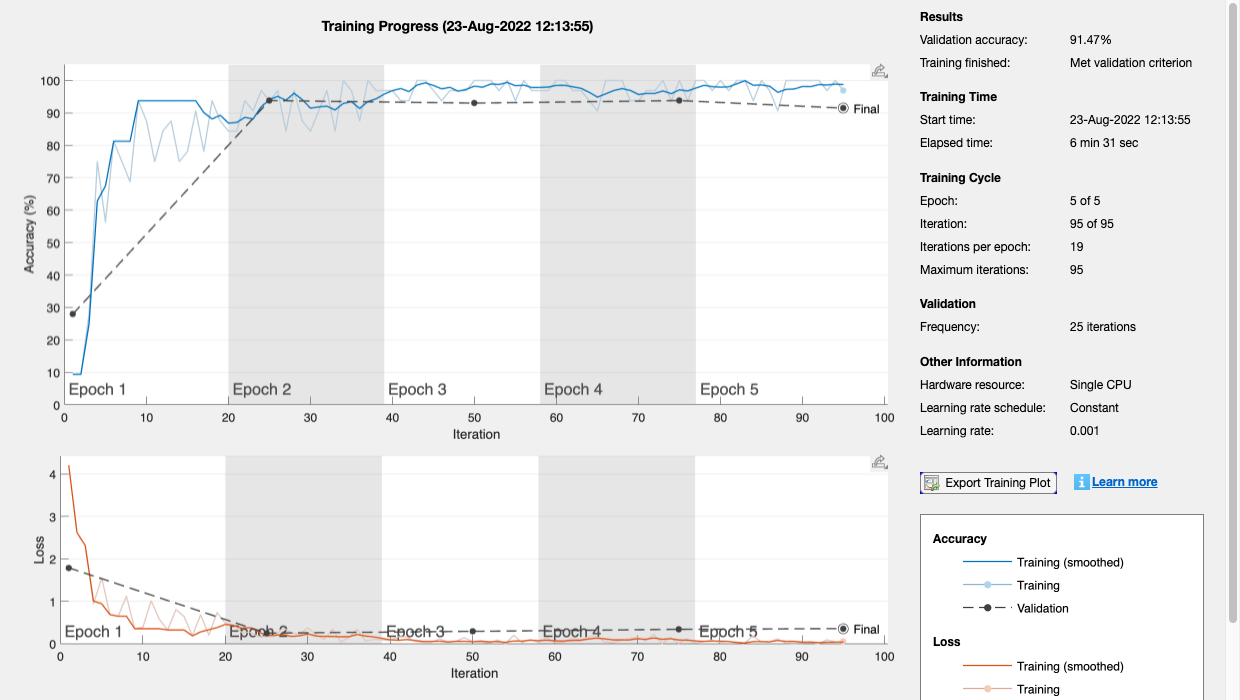

doTraining = true;

if doTraining
    disp('Initialization may take a minute before training begins');
    net_TransferLearning = trainNetwork(DS.auTrainDS, newLayers, trainOpts);
    % If you get out-of-memory error for GPU, go back to trainingOptions and reduce the 'MiniBatchSize'
else
    % load .mat file with trained network
    load('net_TransferLearning.mat')
end

*This ends the training section without DND. Please return to Work_TransferLearning.mlx.*

*Copyright 2022 The MathWorks, Inc.*